# enae404 hw07

vai srivastava

## problem 3

addpath("./.") % path to provided code
addpath("../../../code") % path to custom ENAE404 lib

### part a

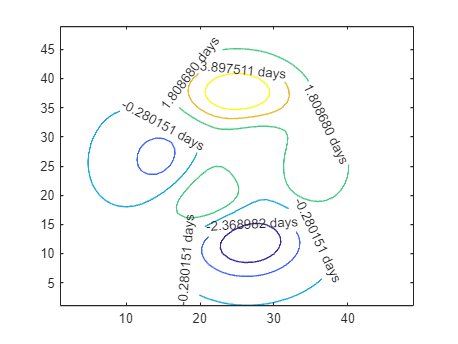

C3 = zeros(45, 500);
Vinf = zeros(45, 500);
TOF = zeros(45, 500);
for h=1:1:45
    for j=1:1:500
        epochs.dep = Provided.ymdhms2jd(2022, 08, 01, 12, 00, 00)+(j-h);
        epochs.arr = Provided.ymdhms2jd(2023, 01, 28, 12, 00, 00)+(j-h);
        TOF(h, j) = epochs.arr-epochs.dep;
        
        [ Earth.loc.dep, Earth.v.dep ] = Provided.findEarth(epochs.dep);
        [ Mars.loc.arr, Mars.v.arr ] = Provided.findMars(epochs.arr);

        [ SC.v.dep, SC.v.arr ] = SFD.solve_lambert(Earth.loc.dep, Mars.loc.arr, TOF(h, j), SFD.mu_Sun, false);
        C3(h, j) = norm(SC.v.dep - Earth.v.dep)^2;
        Vinf(h, j) = norm(SC.v.arr - Mars.v.arr);
    end
end
[C3, Vinf, TOF] = peaks;
contour(peaks, 6)

### part b

foo = "bar"

foo = "bar"

disp(foo)

bar
